close all
clc
clear

# Задание 1-2

## Разомкнутая система

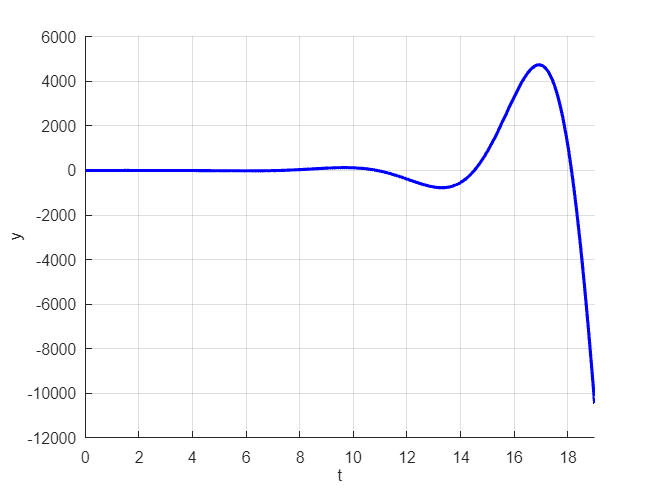

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\1_1.png


%% Время
t_start = 0;
t_end = 19;

%% Коэффициенты
a0 = 1;
a1 = -1;
a2 = 1;

k0 = -1;
k1 = -3;

T_values = [0.1, 0.25, 0.45];
T = T_values(1);


%% Моделирование
% Укажите путь к модели
model_name = 'sim1';  % Имя модели без расширения
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));

% Запуск симуляции
sim_out = sim(model_name);

%% Обработка
% Извлечение результатов
t = sim_out.y1.Time;
y1 = sim_out.y1.Data;
y2 = sim_out.y2.Data;

% Построение графика
fig = figure;
xlabel('t');
ylabel('y');
title('');
grid on;
hold on
xlim([0 t_end])
plot(t, y1, 'LineWidth', 2, Color='b');
save_plot(fig, '1_1.png')

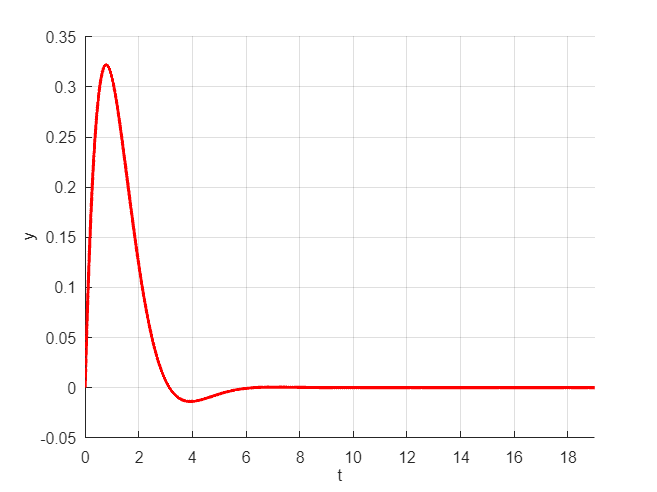

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\1_2.png



% Построение графика
fig = figure;
xlabel('t');
ylabel('y');
title('');
grid on;
hold on
xlim([0 t_end])
plot(t, y2, 'LineWidth', 2, Color='r');
save_plot(fig, '1_2.png')

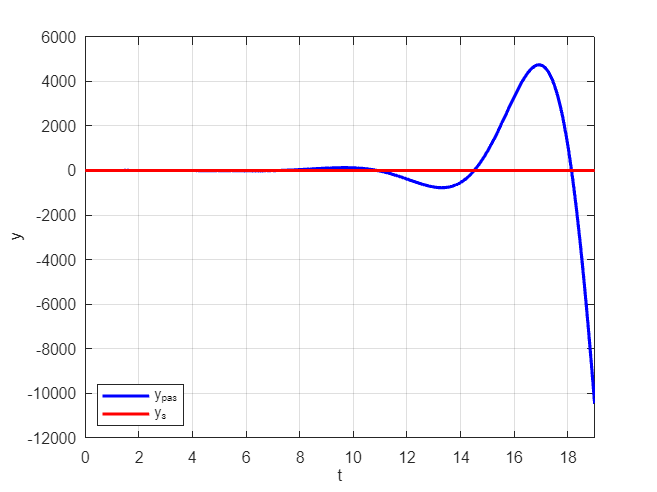

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\1_3.png



% Построение графика
fig = figure;
plot(t, y1, 'LineWidth', 2, Color='b');
xlabel('t');
ylabel('y');
title('');
grid on;
hold on
xlim([0 t_end])
plot(t, y2, 'LineWidth', 2, Color='r');
legend('y_{раз}', 'y_{з}', Location='southwest');
save_plot(fig, '1_3.png')

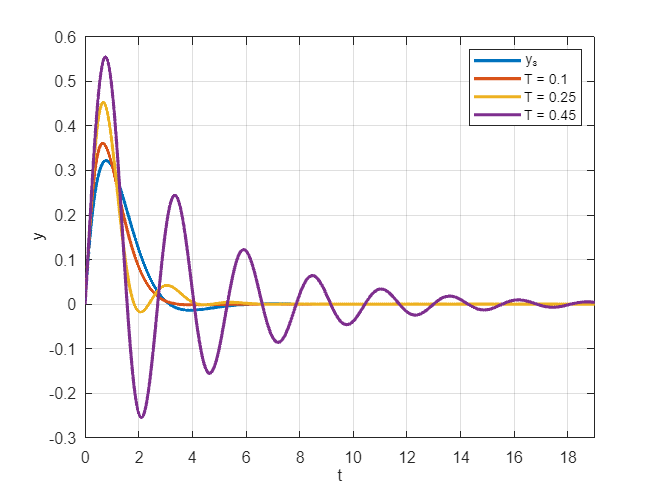

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\2_1.png



% Построение графика
fig = figure;
plot(t, y2, 'LineWidth', 2);
xlabel('t');
ylabel('y');
title('');
grid on;
hold on
xlim([0 t_end])

num_experiments = length(T_values);
legendEntries = cell(1, num_experiments + 1);
legendEntries{1} = 'y_з';

for i = 1:num_experiments
    % Обновить значение T
    T = T_values(i);
    % Запуск симуляции
    sim_out = sim(model_name);
    % Извлечение результатов
    t = sim_out.y3.Time;
    y3 = sim_out.y3.Data;
    plot(t, y3, 'LineWidth', 2);
    legendEntries{i + 1} = ['T = ', num2str(T_values(i))];
end

legend(legendEntries);
save_plot(fig, '2_1.png')

# Задание 3

close all
clc
clear

%% Время
t_start = 0;
t_end = 20;

model_name = 'sim3';  % Имя модели без расширения
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));


reg_sw = 1

reg_sw = 1

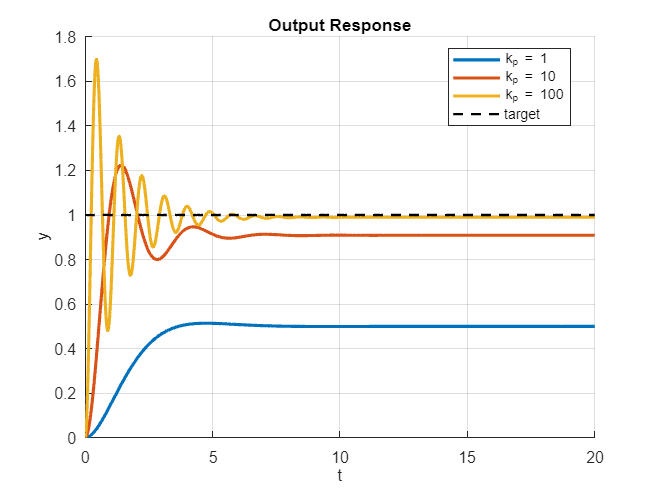

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\3_1.png


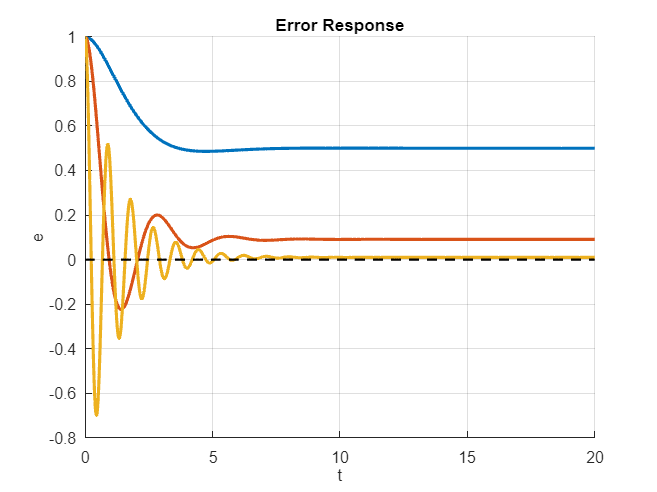

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\3_2.png


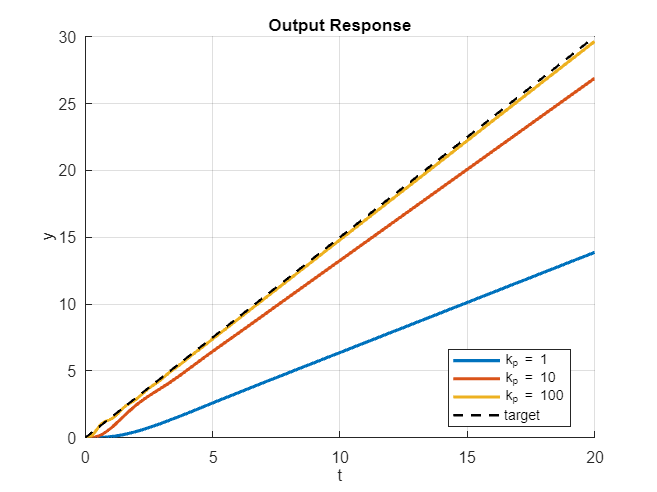

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\3_3.png


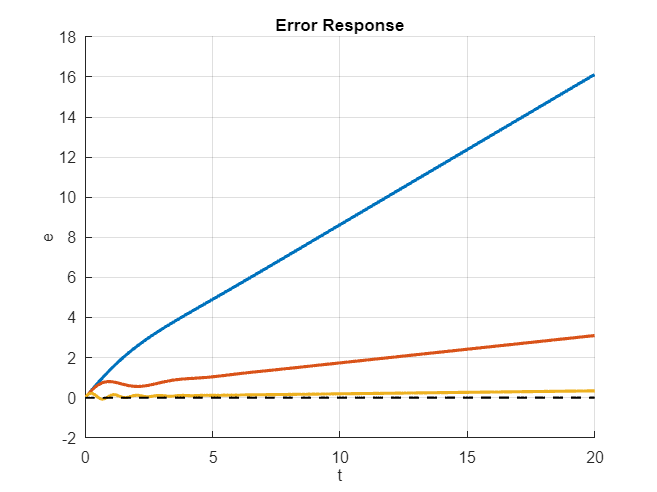

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\3_4.png


kp_values = [1 10 100];
ki = 0;
in_sw_values = [1 2];

for i = 1:length(in_sw_values)
    in_sw = in_sw_values(i);

    fig1 = figure(2*i - 1);
    xlabel('t');
    ylabel('y');
    title('Output Response');
    grid on;
    hold on;
    xlim([0 t_end]);

    fig2 = figure(2*i);
    xlabel('t');
    ylabel('e');
    title('Error Response')
    grid on;
    hold on;
    xlim([0 t_end]);

    for j = 1:length(kp_values)
        kp = kp_values(j);
        sim_out = sim(model_name);
        t = sim_out.y.Time;
        y = sim_out.y.Data;
        e = sim_out.e.Data;
        figure(2*i - 1);
        plot(t, y, 'LineWidth', 2, 'DisplayName', ['k_p = ', num2str(kp)]);
        figure(2*i);
        plot(t, e, 'LineWidth', 2, 'DisplayName', ['k_p = ', num2str(kp)]);
    end

    figure(2*i - 1);
    input = sim_out.input.Data;
    plot(t, input, 'LineWidth', 1.5, 'DisplayName', 'target', 'Color', 'k', 'LineStyle', '--');
    legend(Location='best');
    save_plot(fig1, ['3_', num2str(2*i - 1), '.png'])

    figure(2*i);
    target = zeros(length(t), 1);
    plot(t, target, 'LineWidth', 1.5, 'DisplayName', 'target', 'Color', 'k', 'LineStyle', '--');
    % legend(Location='best');
    save_plot(fig2, ['3_', num2str(2*i), '.png'])
end

# Задание 4

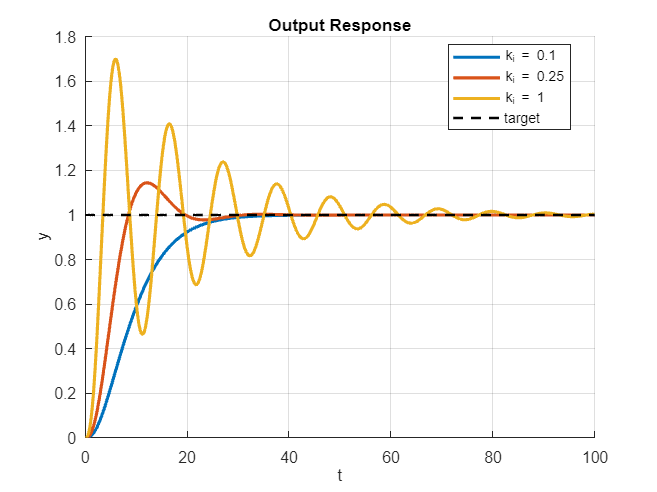

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\4_1.png


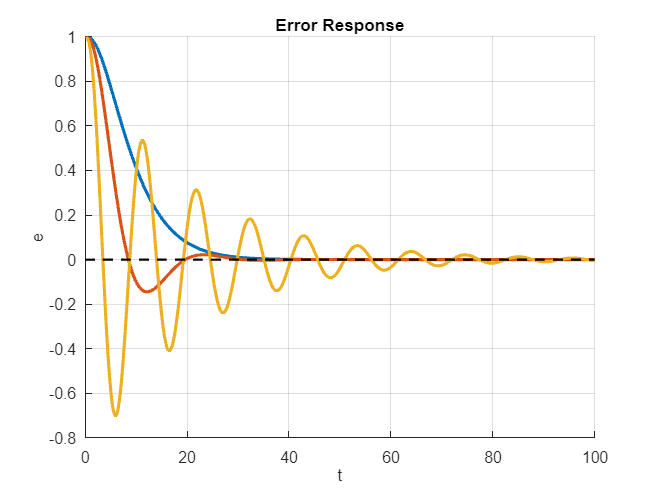

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\4_2.png


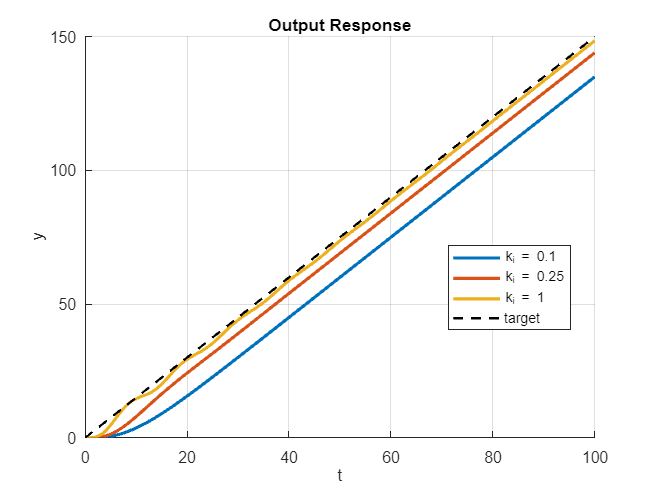

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\4_3.png


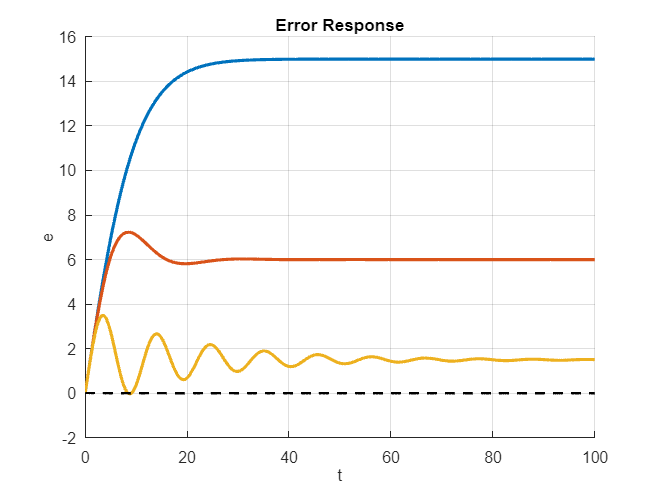

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\4_4.png


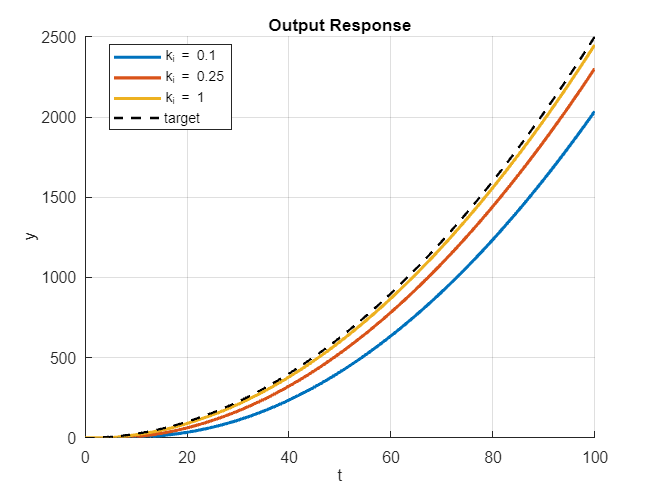

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\4_5.png


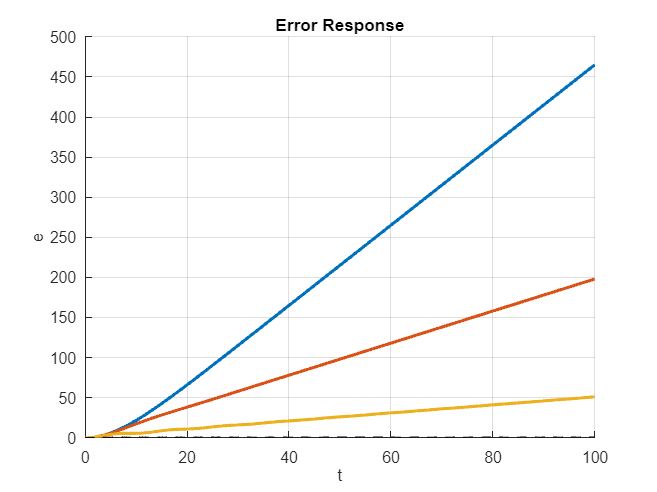

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\4_6.png


close all
clc
clear

%% Время
t_start = 0;
t_end = 100;

model_name = 'sim3';  % Имя модели без расширения
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));
reg_sw = 2;
kp = 0;
ki_values = [0.1 0.25 1];
in_sw_values = [1 2 3];

for i = 1:length(in_sw_values)
    in_sw = in_sw_values(i);

    fig1 = figure(2*i - 1);
    xlabel('t');
    ylabel('y');
    title('Output Response');
    grid on;
    hold on;
    xlim([0 t_end]);

    fig2 = figure(2*i);
    xlabel('t');
    ylabel('e');
    title('Error Response')
    grid on;
    hold on;
    xlim([0 t_end]);

    for j = 1:length(ki_values)
        ki = ki_values(j);
        sim_out = sim(model_name);
        t = sim_out.y.Time;
        y = sim_out.y.Data;
        e = sim_out.e.Data;
        figure(2*i - 1);
        plot(t, y, 'LineWidth', 2, 'DisplayName', ['k_i = ', num2str(ki)]);
        figure(2*i);
        plot(t, e, 'LineWidth', 2, 'DisplayName', ['k_i = ', num2str(ki)]);
    end

    figure(2*i - 1);
    input = sim_out.input.Data;
    plot(t, input, 'LineWidth', 1.5, 'DisplayName', 'target', 'Color', 'k', 'LineStyle', '--');
    legend(Location='best');
    save_plot(fig1, ['4_', num2str(2*i - 1), '.png'])

    figure(2*i);
    target = zeros(length(t), 1);
    plot(t, target, 'LineWidth', 1.5, 'DisplayName', 'target', 'Color', 'k', 'LineStyle', '--');
    % legend(Location='best');
    save_plot(fig2, ['4_', num2str(2*i), '.png'])
end

# Задание 5

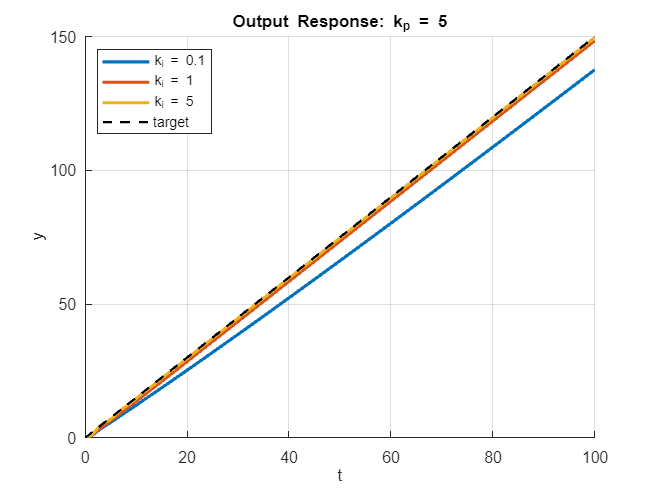

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_2_kp_5_output.png


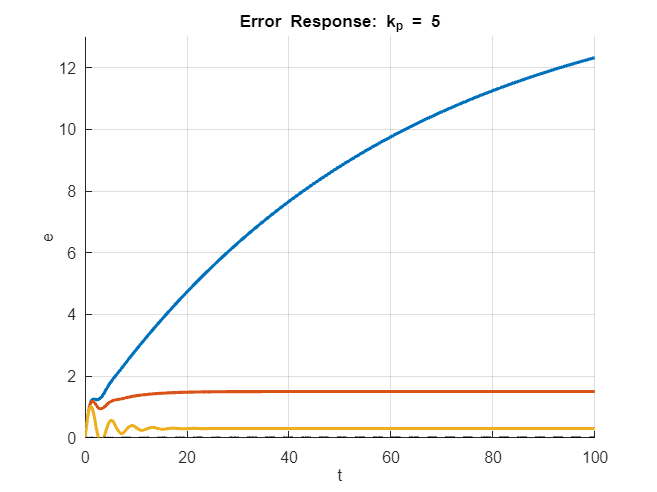

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_2_kp_5_error.png


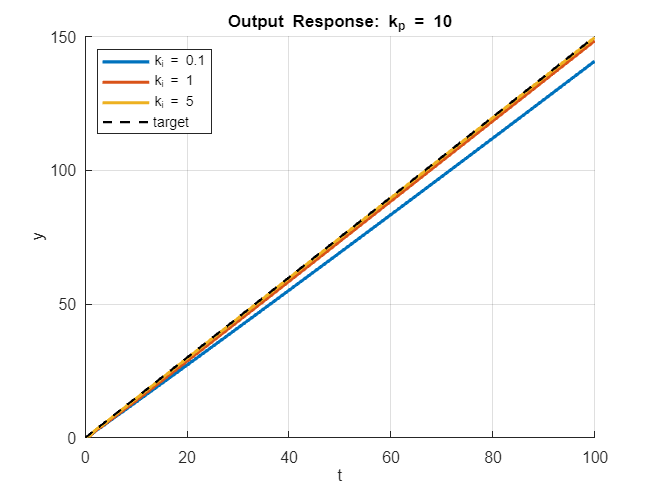

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_2_kp_10_output.png


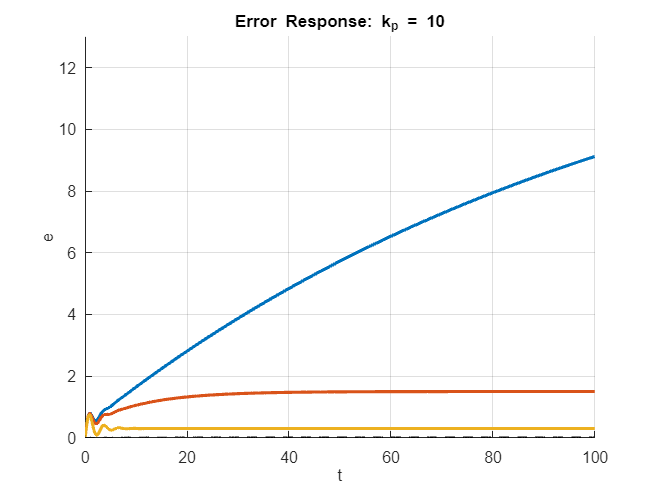

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_2_kp_10_error.png


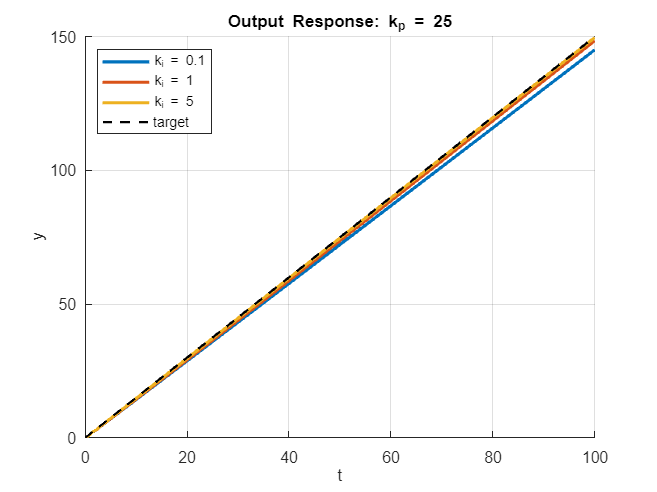

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_2_kp_25_output.png


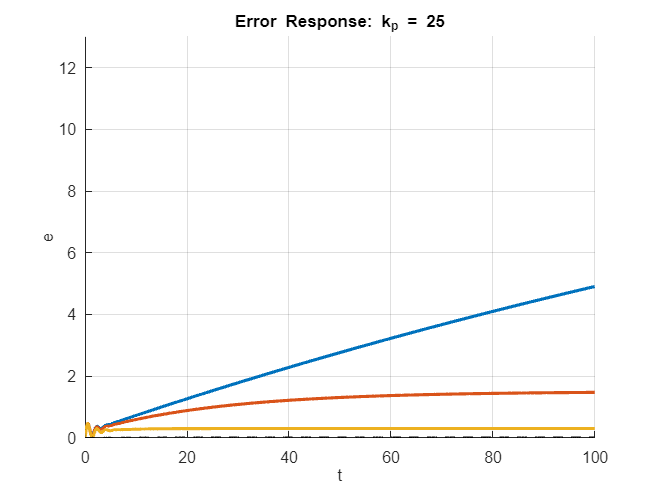

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_2_kp_25_error.png


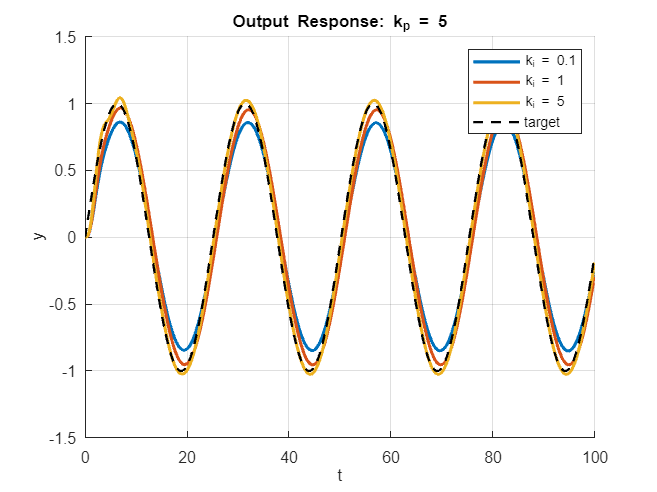

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_4_kp_5_output.png


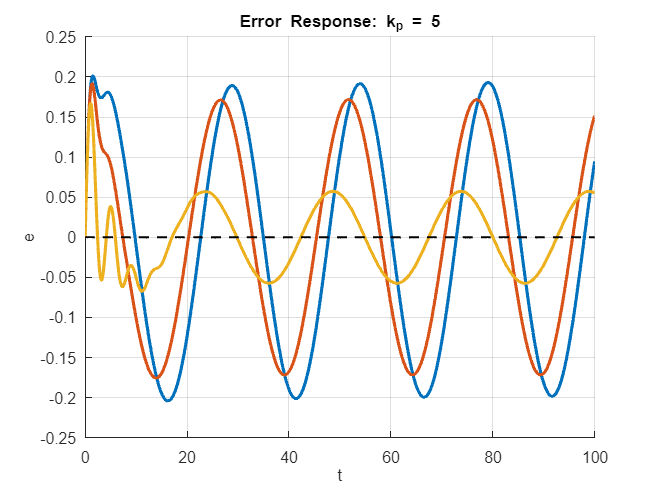

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_4_kp_5_error.png


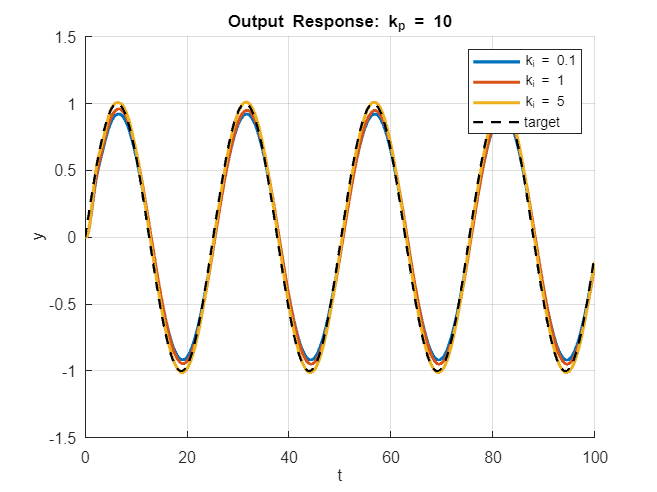

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_4_kp_10_output.png


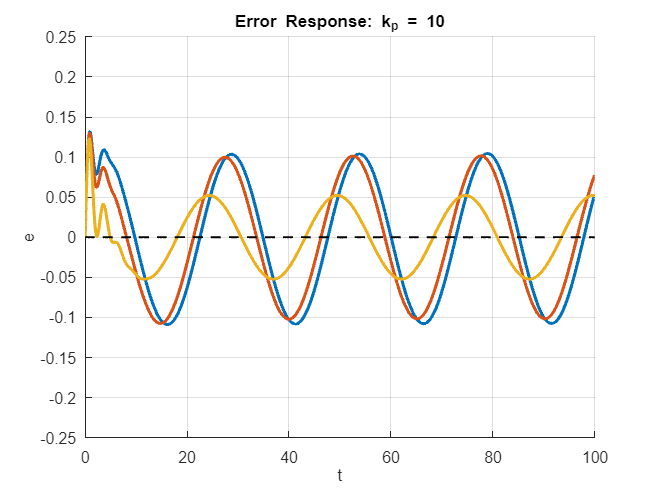

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_4_kp_10_error.png


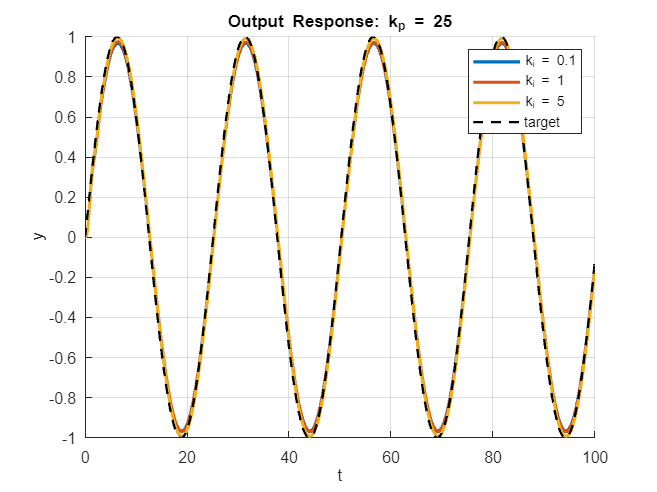

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_4_kp_25_output.png


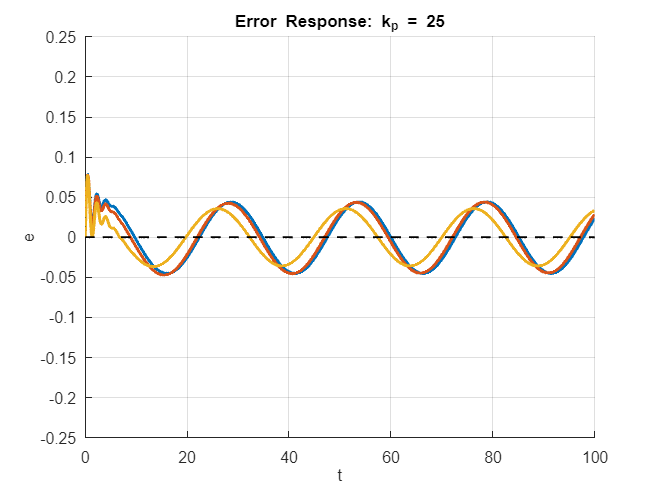

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\input_4_kp_25_error.png


close all
clc
clear

%% Время
t_start = 0;
t_end = 100;

model_name = 'sim3';  % Имя модели без расширения
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Относительная погрешность 
set_param(model_name, 'StartTime', num2str(t_start)); % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));

% Параметры регулятора
reg_sw = 3;
kp_values = [5, 10, 25];    % Новые значения k_p
ki_values = [0.1, 1, 5];   % Значения k_i
in_sw_values = [2, 4];     % Типы входных сигналов

% Цикл по входным сигналам
for i = 1:length(in_sw_values)
    in_sw = in_sw_values(i);

    for k = 1:length(kp_values)
        kp = kp_values(k);

        % Создаем отдельные фигуры для каждого kp
        fig1 = figure; % Фигура для выходного сигнала y
        xlabel('t');
        ylabel('y');
        title(['Output Response: k_p = ', num2str(kp)]);
        grid on; hold on;
        xlim([0 t_end]);

        fig2 = figure; % Фигура для ошибки e
        xlabel('t');
        ylabel('e');
        title(['Error Response: k_p = ', num2str(kp)]);
        grid on; hold on;
        xlim([0 t_end]);
        if (in_sw == 2)
            ylim([0 13])
        else
            ylim([-0.25 0.25])
        end

        % Цикл по ki для текущего kp
        for j = 1:length(ki_values)
            ki = ki_values(j);

            % Запуск симуляции
            sim_out = sim(model_name);
            t = sim_out.y.Time;
            y = sim_out.y.Data;
            e = sim_out.e.Data;

            % Построение графиков для y
            figure(fig1);
            plot(t, y, 'LineWidth', 2, ...
                 'DisplayName', ['k_i = ', num2str(ki)]);

            % Построение графиков для e
            figure(fig2);
            plot(t, e, 'LineWidth', 2, ...
                 'DisplayName', ['k_i = ', num2str(ki)]);
        end

        % Добавляем целевой сигнал на график y
        figure(fig1);
        input = sim_out.input.Data;
        plot(t, input, 'LineWidth', 1.5, 'DisplayName', 'target', ...
             'Color', 'k', 'LineStyle', '--');
        % legend(Location='best');
        if (in_sw == 2)
            legend(Location='northwest');
        else
           legend();
        end
        save_plot(fig1, ['input_', num2str(in_sw),'_kp_', num2str(kp),  '_output.png']);

        % Добавляем нулевую ошибку на график e
        figure(fig2);
        target = zeros(length(t), 1);
        plot(t, target, 'LineWidth', 1.5, 'DisplayName', 'target', ...
             'Color', 'k', 'LineStyle', '--');
        % legend(Location='best');
        save_plot(fig2, ['input_', num2str(in_sw),'_kp_', num2str(kp),  '_error.png']);
    end
end

# Задание 6

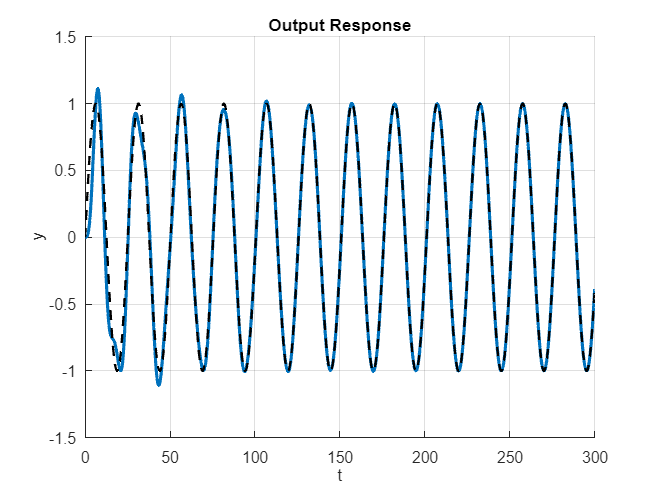

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\6_1.png


%% Время
t_start = 0;
t_end = 300;

model_name = 'sim6';  % Имя модели без расширения
load_system(model_name);

% Настройка параметров симуляции
set_param(model_name, 'Solver', 'VariableStepAuto'); % Переменный шаг времени
set_param(model_name, 'RelTol', '1e-8');            % Установить относительную погрешность 
set_param(model_name, 'StartTime', num2str(t_start));             % Начальное время симуляции
set_param(model_name, 'StopTime', num2str(t_end));

sim_out = sim(model_name);
t = sim_out.y.Time;
e = sim_out.e.Data;
y = sim_out.y.Data;


fig1 = figure();
xlabel('t');
ylabel('y');
title('Output Response');
grid on;
hold on;
xlim([0 t_end]);
plot(t, y, 'LineWidth', 2, 'DisplayName', ['k_p = ', num2str(kp)]);
input = sim_out.input.Data;
plot(t, input, 'LineWidth', 1.5, 'DisplayName', 'target', 'Color', 'k', 'LineStyle', '--');
% legend(Location='best');
save_plot(fig1, '6_1.png')

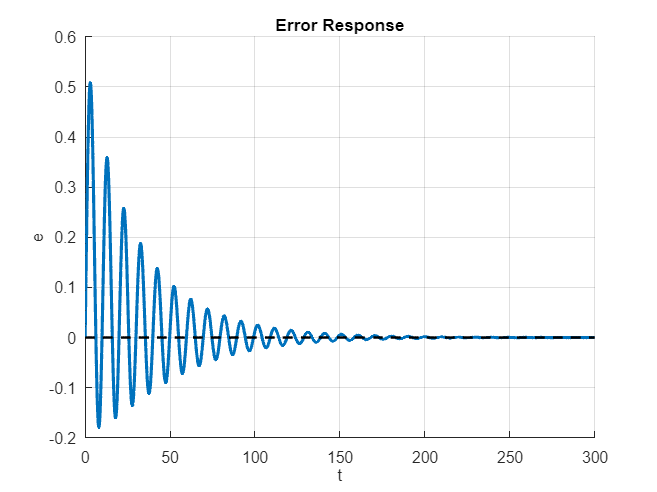

График сохранен по пути: C:\Users\vasil\Desktop\lsau\lab4\report\images\6_2.png



fig2 = figure();
xlabel('t');
ylabel('e');
title('Error Response')
grid on;
hold on;
xlim([0 t_end]);
plot(t, e, 'LineWidth', 2, 'DisplayName', ['k_p = ', num2str(kp)]);
target = zeros(length(t), 1);
plot(t, target, 'LineWidth', 1.5, 'DisplayName', 'target', 'Color', 'k', 'LineStyle', '--');
save_plot(fig2, '6_2.png')

function save_plot(fig, save_filename)
    save_path = 'C:\Users\vasil\Desktop\lsau\lab4\report\images'; % Замените на свой путь
    
    % Полный путь к файлу
    full_save_path = fullfile(save_path, save_filename);
    
    % Сохранение графика
    exportgraphics(fig, full_save_path, "Resolution", 600); 
    disp(['График сохранен по пути: ' full_save_path]);
end